# Analisi Algoritmo Risolve

In questa documentazione si mostreranno i casi di test relativi all'algoritmo` risolve`.

# Test di accuratezza

Il  test di accuratezza da informazioni su qual'è l'errore prodotto dall'algoritmo` risolve` sulla soluzione calcolata. Infatti via software andiamo a risolvere un problema che è perturbato dove i dati del sistema hanno errore di round off. Non si potrà mai avere una soluzione del sistema che sia vera ma vogliamo capire quanto essa ci  si avvicini . Si utilizzerà la funzione `Calcolo_Accuratezza `che a partire da un problema con relativa soluzione(**parametri di input**) calcola l'errore relativo della soluzione. La funzione restituirà oltre all'errore relativo anche l'indice di condizionamento.Quest'ultimo  è strettamento legato all'errore che possiamo avere, infatti,ci da una misura di quanto l'errore di round off sui dati di input venga amplificato nell'errore di uscita. 

Si analizzeranno tre casi:

- **Matrice triangolare superiore: **utilizzo l'algoritmo `back_substitution` per risolvere il sistema.

- **Matrice triangolare inferiore: **utilizzo l'algoritmo di `forward_substitution` per risolvere il sistema.

- **Matrice piena: **utilizzo l'algoritmo di Gauss con` pivoting parziale virtuale` per calcolare la soluzione.

In ognuno dei 3 casi potremo avere che la matrice di input è **mal condizionata** o  **ben condizionata**,nell'ultimo caso come si osserverà dal codice si impone che la matrice sia non singolare ponendo gli elementi della diagonale almeno pari ad 1.

%% Matrice Triangolare Superiore ben condizionata
A = triu(rand(200)) + 2*diag(ones(200,1)); 
x = ones(200,1);
b = A*x;
[indice_cond, err ] = Calcolo_Accuratezza(A,x,b,'sup')

indice_cond = 354.6484

err = 1.8894e-13

%% Matrice Triangolare Superiore mal condizionata
A = triu(rand(200));
x = ones(200,1);
b = A*x;
[indice_cond,err] =Calcolo_Accuratezza (A,x,b,'sup')

indice_cond = 1.0993e+18

err = 9.6526e+23

In tal caso si sono perse tutte le cifre significative del risultato.

%% Matrice Triangolare inferiore ben condizionata
A = tril(rand(200)) + 2*diag(ones(200,1)); 
x = ones(200,1);
b = A*x;
[indice_cond, err] = Calcolo_Accuratezza(A,x,b,'inf')

indice_cond = 403.7146

err = 1.6008e-14

%% Matrice Triangolare inferiore mal condizionata
A = tril(rand(200)); 
x = ones(200,1);
b = A*x;
[indice_cond, err] = Calcolo_Accuratezza(A,x,b,'inf')

indice_cond = 8.6802e+18

err = 1.8634e+22

Per le matrici piene che prevedono l'utilizzo dell'algoritmo di Gauss con pivoting si verifica la validità del **teorema di Wilkinson**.

%%Matrice Piena
A = rand(200);
x = ones(200,1);
b = A*x;
[indice_cond, err, residuo] =Calcolo_Accuratezza (A,x,b,'full')

indice_cond = 7.7572e+03

err = 1.4724e-13

residuo = 5.3632e-16

Il residuo e l'errore in tal caso sono quasi uguali la loro differenza è circa pari all'indice di condizionamento.

%%Matrice di Hilbert:molto malcondizionata
A =hilb(10);
x = ones(10,1);
b = A*x;
[indice_cond, err, residuo] = Calcolo_Accuratezza(A,x,b,'full')

indice_cond = 1.6025e+13

err = 1.6307e-04

residuo = 2.0685e-16

Nel caso delle matrici piene `Calcolo_Accuratezza` restituisce anche il **residuo **che notiamo essere tanto più vicino all'errore relativo quanto più l'indice di condizionamento è piccolo. Infatti l'errore per tali matrici(quando ben condizionate) può essere espresso come il prodotto tra l'indice di condizionamento ed il residuo stesso.

# Valutazione Performance

Attraverso la funzione `valuta_performance `è stato valutato il tempo di esecuzione dell'algoritmo implementato. A partire dalla generazione di  matrici random da 1 fino a 200 elementi sono state effettuate tre misurazioni a seconda del tipo di matrici considerate. 

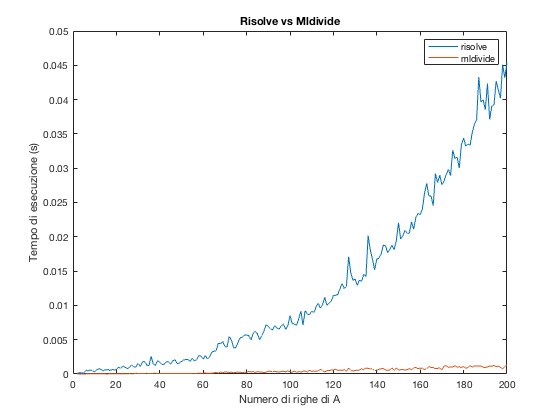

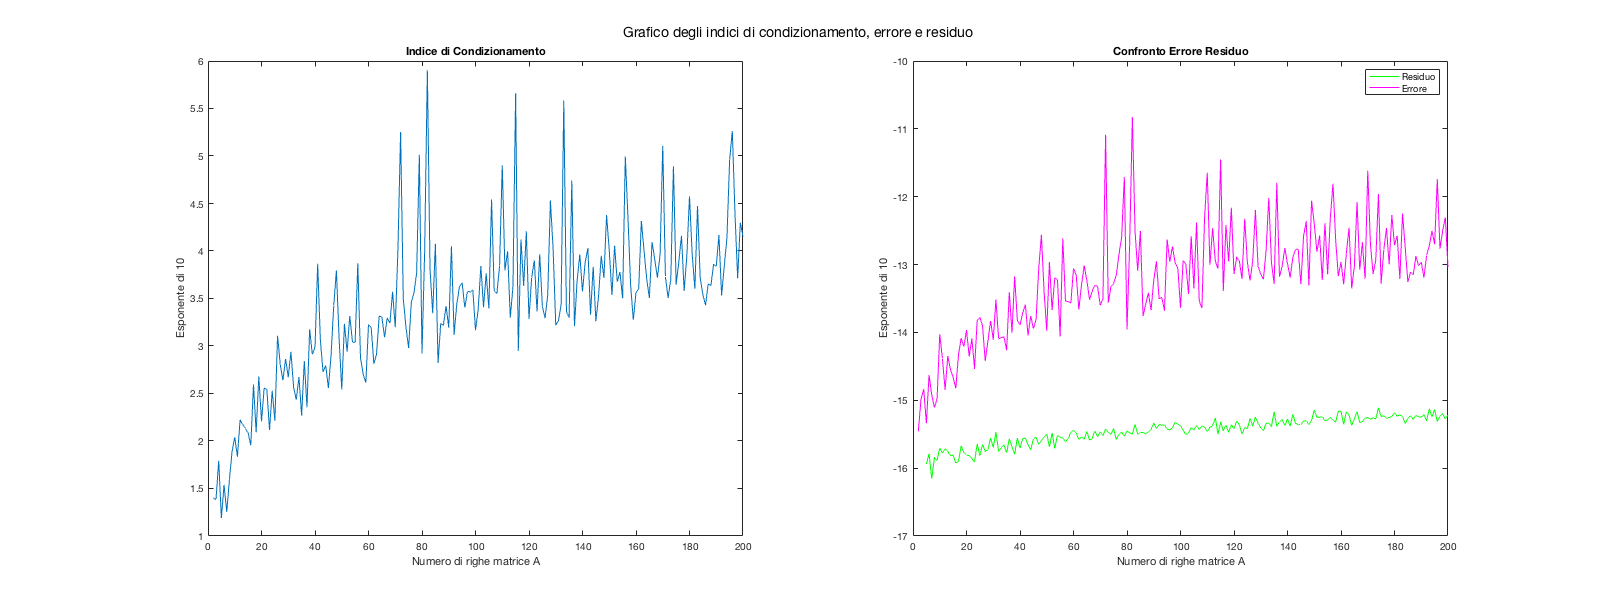

Valuta_Performance(2,200,1,'full')

Nel caso della matrice piena è stato effettuato un confronto con i tempi di esecuzione della funzione `mldivide(/)`. Quest'ultima è il miglior algoritmo presente in Matlab per la risoluzione di sistemi lineari. Si è scelto per maggior chiarezza di graficare l'andamento dell'indice di condizionamento,errore e residuo per le matrici generate.

# Test di robustezza

Per valutare la robustezza dell'algoritmo è stata implementata una test suite. I casi di test sono stati scelti a partire dalle condizioni di errore o warning che possono avere luogo. Ogni caso di test lo descriveremo brevemente a partire dai parametri di input e dalla funzionalità che  viene testata. Il numero di casi di test è: 16 ,implementati in una classe definita dal matlab *matlab.unittest.TestCase*. In tal modo si è automatizzato il processo di esecuzione dei test. Le istruzioni per eseguire i test saranno mostrate successivamente.

Di seguito sono mostrati  i casi di test  più rilevanti che sono stati effettuati ,rispettando la precedenza tra essi.

## Test case 1

Verifica l'errore nel caso in cui la matrice A è vuota.

## Input


$$\begin{array}{l}
A=\left\lbrack \right\rbrack \\
b=\mathrm{rand}\left(3,1\right)\\
\mathrm{opt}\ldotp \mathrm{full}=\mathrm{true}\\
\mathrm{opt}\ldotp \mathrm{inf}=\mathrm{false}\\
\mathrm{opt}\ldotp \mathrm{sup}=\mathrm{false}
\end{array}$$


## Test case 2

Verifica l'errore nel caso in cui la matrice A non è numerica.

## Input


$$\begin{array}{l}
A=\left\lbrack 3,2;,\mathrm{'a'},4\right\rbrack \\
b=\mathrm{rand}\left(3,1\right)\\
\mathrm{opt}\ldotp \mathrm{full}=\mathrm{true}\\
\mathrm{opt}\ldotp \mathrm{inf}=\mathrm{false}\\
\mathrm{opt}\ldotp \mathrm{sup}=\mathrm{false}
\end{array}$$


## Caso di test 3                                                                                                                   

Verifica l'errore nel caso in cui la matrice A è sparsa.

## Input


$$\begin{array}{l}
A=\mathrm{sparse}\left(A\right)\\
b=\mathrm{rand}\left(3,1\right)\\
\mathrm{opt}\ldotp \mathrm{full}=\mathrm{true}\\
\mathrm{opt}\ldotp \mathrm{inf}=\mathrm{false}\\
\mathrm{opt}\ldotp \mathrm{sup}=\mathrm{false}
\end{array}$$


## Caso di test 5                                                                                                                      

 Verifica l'errore nel caso in cui la matrice A non è quadrata.

## Input


$$\begin{array}{l}
A=\left\lbrack 2\text{ }3\text{ }4;4\text{ }5\text{ }3\right\rbrack \\
\text{b}=\mathrm{rand}\left(3,1\right)\\
\mathrm{opt}\ldotp \mathrm{full}=\mathrm{true}\\
\mathrm{opt}\ldotp \mathrm{inf}=\mathrm{false}\\
\mathrm{opt}\ldotp \mathrm{sup}=\mathrm{false}
\end{array}$$


## Test case 6

Verifica l'errore nel caso in cui b non è un vettore reale.

## Input


$$\begin{array}{l}
A=\mathrm{rand}\left(3,3\right)\\
b=\left\lbrack 3;4;\mathrm{'a'}\right\rbrack \\
\mathrm{opt}\ldotp \mathrm{full}=\mathrm{true}\\
\mathrm{opt}\ldotp \mathrm{inf}=\mathrm{false}\\
\mathrm{opt}\ldotp \mathrm{sup}=\mathrm{false}\\

\end{array}$$


## Test case 8

Verifica l'errore nel caso in cui il vettore b ha un numero di righe diverso dal numero di righe di A.

## Input


$$\begin{array}{l}
A=\mathrm{rand}\left(4\right)\\
b=\left\lbrack 1;2;3\right\rbrack \\
\mathrm{opt}\ldotp \mathrm{full}=\mathrm{true}\\
\mathrm{opt}\ldotp \mathrm{inf}=\mathrm{false}\\
\mathrm{opt}\ldotp \mathrm{sup}=\mathrm{false}
\end{array}$$


## Test case 9

 Verifica se il campo opt è una struttura.

## Input


$$\begin{array}{l}
A=\mathrm{rand}\left(3,3\right)\\
b=\mathrm{rand}\left(3,1\right)\\
\mathrm{opt}=\mathrm{'a'}
\end{array}$$


## Test case 10

Verifica l'errore nel caso in cui il campo di opt non sia uno tra: inf, sup, full.

## Input


$$A=\text{rand}\left(3,3\right)$$



$$b=\text{rand}\left(3,1\right)$$



$$\text{opt}\ldotp \text{sparsa}=\mathrm{true}$$


## Test case 12

Verifica l'errore nel caso in cui più campi di opt assumono valore true.

## Input


$$\begin{array}{l}
A=\mathrm{rand}\left(3,3\right)\\
b=\mathrm{rand}\left(3,1\right)\\
\mathrm{opt}\ldotp \mathrm{sup}=\mathrm{true}\\
\mathrm{opt}\ldotp \mathrm{inf}=\mathrm{true}\\
\mathrm{opt}\ldotp \mathrm{full}=\mathrm{true}
\end{array}$$


## Test case 13

Verifica l'errore nel caso in cui la matrice A non è coerente con il campo opt specificato.

## Input


$$\begin{array}{l}
A=\mathrm{rand}\left(3,3\right)\\
b=\mathrm{rand}\left(3,1\right)\\
\mathrm{opt}\ldotp \mathrm{inf}=\mathrm{true}\\
\mathrm{opt}\ldotp \mathrm{full}=\mathrm{false}\\
\mathrm{opt}\ldotp \mathrm{sup}=\mathrm{false}
\end{array}$$


## Caso di test 16                                                                                                                      

 Verifica l'errore nel caso in cui la matrice A è triangolare superiore e singolare.

## Input


$$\begin{array}{l}
A=\mathrm{triu}\left(\mathrm{rand}\left(3\right)\right)\\
A\left(1,1\right)=0\\
b=\mathrm{rand}\left(3,1\right)\\
\mathrm{opt}\ldotp \mathrm{full}=\mathrm{false}\\
\mathrm{opt}\ldotp \mathrm{inf}=\mathrm{false}\\
\mathrm{opt}\ldotp \mathrm{sup}=\mathrm{true}
\end{array}$$


***Osservazione : ****Stesso discorso vale per il caso di test in cui la matrice A è triangolare inferiore e singolare. Inoltre questa condizione non viene verificata sulla matrice di input per l'algoritmo di Gauss implementato. Infatti ,la versione implementata con pivot parziale trova**** il pivot**** come massimo della relativa sottocolonna. Nel caso in cui il massimo trovato sia zero, la matrice sarà singolare. Dunque per tale ragionamento si è scelto di restituire "errore" quando si verifica tale condizione nel corpo dell'algoritmo di Gauss implementato.*

## Esecuzione  Test suite

Vengono effettuati i test a partire dagli input definiti in precedenza.

result1 = runtests('TEST_SUITE.m')

Running TEST_SUITE
.......... ......
Done TEST_SUITE
__________



result1 =   1×16 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   16 Passed, 0 Failed, 0 Incomplete.
   0.18473 seconds testing time.


table(result1)

ans = 16×6 table
             Name              Passed    Failed    Incomplete    Duration       Details   
    _______________________    ______    ______    __________    _________    ____________

    'TEST_SUITE/TestCase1'     true      false       false        0.025673    [1×1 struct]
    'TEST_SUITE/TestCase2'     true      false       false        0.032312    [1×1 struct]
    'TEST_SUITE/TestCase3'     true      false       false        0.027049    [1×1 struct]
    'TEST_SUITE/TestCase4'     true      false       false        0.010402    [1×1 struct]
    'TEST_SUITE/TestCase5'     true      false       false       0.0060637    [1×1 struct]
    'TEST_SUITE/TestCase6'     true      false       false       0.0070288    [1×1 struct]
    'TEST_SUITE/TestCase7'     true      false    

## Riferimenti               

- Testing in Matlab: [https://it.mathworks.com/help/matlab/matlab-unit-test-framework.html](https://it.mathworks.com/help/matlab/matlab-unit-test-framework.html)

- Misura di Performance in Matlab [https://it.mathworks.com/help/matlab/performance-and-memory.html](https://it.mathworks.com/help/matlab/performance-and-memory.html)

## Autori                                                                                                                          

** Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936**